## PROBLEM 2.0

%{
ES 115 CLASS PROJECT PROBLEM 2.0
PROBLEM TITLE: TEMPERATURE SIMULATION USING GAUSSIAN DISTRIBUTION
DESCRIPTION: This program simulates external temperature variations over a
             2 hour period using a normal (Gaussian) distribution.
PURPOSE: To model realistic environmental temperature fluctuations and
         analyze extreme values affecting a medical container.
INPUT:
    ~ Mean Temperature (Fahrenheit)
    ~ Standard deviations
    ~ Time
OUTPUTS:
    ~ Simulated temperature values
    ~ Maximum temperature
    ~ Minimum temperature
    ~ Time at which maximum temperature occurs
    ~ Time at which minimum temperature occurs
ENGINEERING ALGORITHIMS:
- Create a time vector from 0 to 120 minutes in 0.5min steps
- Generate normally distributed random temperatures
- Scale using mean and standard deviation
- Plot temperature vs time
- Find maximum and minimum temperatures
- Identify corresponding times
MATLAB TOOLS/FUNCTIONS
- linspace
- randn
- plot
- max, min
- indexing
%}

### 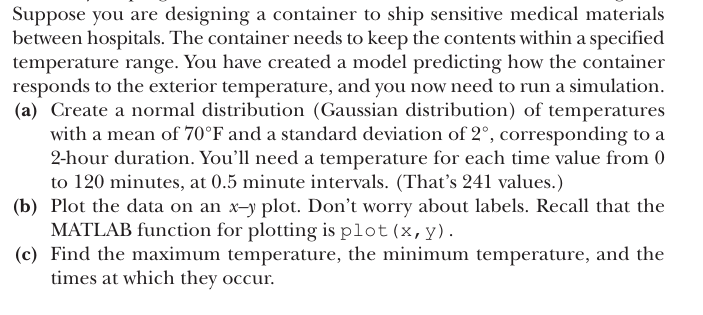

### SOLUTION STEPS TO PROBLEM 2:

- Define given values and time array

- Generate Gaussian distribution using the mean temperature, standard deviation, and the randn function

- Find maximum and minimum values using the max and min functions alongside with the index function.

- Correspond the times with the max and min values of temperatures

- Display the results using the fprintf function

%Given Values
mean_temp = 70; % Mean temperature given in degrees in Fahrenheit
std_dev = 2;    % Standard deviation given in degrees in Fahrenheit

time = 0:0.5:120; % Time vector from 0 to 120 minutes in 0.5 min steps

temp = mean_temp + std_dev * randn(size(time)); % Generate normally distributed temperatures

plot(time, temp) %Plots a graph of temperature against time


[max_temp, idx_max] = max(temp); % Find maximum temperature and its index in the vector
[min_temp, idx_min] = min(temp); % Find minimum temperature and its index in the vector

t_max = time(idx_max); % Extract timestamp corresponding to the maximum value
t_min = time(idx_min); % Extract timestamp corresponding to the minimum value

% Print peak temperature and its time
fprintf('Maximum Temperature: %.2f Degrees Fahrenheit at %.2f minutes\n', max_temp, t_max);
% Print trough temperature and its time
fprintf('Minimum Temperature: %.2f Degrees Fahrenheit at %.2f minutes\n', min_temp, t_min);